##  0. Housekeeping

clear;
addpath('Figures');
addpath('Figures/Figs');
addpath('Functions');
addpath('Mats');
addpath('Mats - Consumption');
addpath('Mats - Distributions');
addpath('Mats - Job Value and Wage');
addpath('Mats - Savings')
addpath('Mats - Welfare');
addpath('Results');

## 1. Structural Parameter Settings

### 1.1. Structural Parameters

global I J daaF daaB dz lame amin amax gam aagrid zgrid;
alf  = 0.3;     % Production Parameter          fr. Bardoczy
bet  = 0.72;    % Worker's bargaining power     fr. Bardoczy    
gam  = 1;       % Utility function              fr. Ben Moll Aiyagari Diffusion
del  = 0.021;   % Depreciation Rate             fr. Ben Moll Aiyagari Diffusion
eta  = 0.72;    % LM Tightness Elasticity       fr. Bardoczy
phi  = 0.395;   % Flow Cost of Vacancy          fr. Bardoczy (It's \xi in Bardoczy)
rho  = 0.01;    % Discount rate                 fr. Ben Moll Aiyagari Diffusion
chi  = 1.7935;  % Matching Efficiency           fr. Bardoczy                
lame = 0.1038;  % Separation Intensity          fr. Bardoczy and several other liter0ature
hp   = 0.0001;  % Home Production

### 1.2. Asset Grid

amin = 0; 
amax = 2500;
I = 1500;
J = 15;
x = linspace(0,1,I)';
coeff = 1.3; power = 2.8;
xx  = x + coeff*x.^power;
xmax = max(xx); 
xmin = min(xx);
agrid = (amax-amin)/(xmax - xmin)*xx + amin;
aagrid = agrid*ones(1,J);

daF = ones(I,1);
daB = ones(I,1);

daF(1:I-1) = agrid(2:I)-agrid(1:I-1);
daB(2:I  ) = agrid(2:I)-agrid(1:I-1);

daF(I) = daF(I-1); 
daB(1) = daB(2);

daaF = repmat(daF,1,J);
daaB = repmat(daB,1,J);

### 1.3. Productivity Grid

ze =  1; 
zu = 0.65;
zmin = zu; 
zmax = ze;

zgrid = linspace(zmin, zmax, J)';
zzgrid = ones(I,1) * zgrid';
zgridREP= repelem(zgrid,I);
dz = (zmax - zmin)/(J-1);

the  = .25;
theu = .50;
mue = the*(ze - zgrid);
muu = the*(zu - zgrid);

## 2. The Transition Matrix for the Diffusion Process  

Ce = MatrixC(mue);
Cu = MatrixC(muu);
C = blkdiag(sparse(Ce), sparse(Cu));

## 3. Solution Parameter Settings

tolHJB = 1e-10;  % tolerance level for HJB equations 12?
tolENT = 1e-5;  % tolerance level for free entry condition
tolMKT = 1e-5;  % tolerance level for asset market clearing
n = 300; % maximum number of iterations when solving HJB equation
N = 1000;  % maximum number of iterations in outer loop
Delta = 500;  % step size in HJB equation
dTheta = 1e-1;  % step size in updating theta
relax = .999;
kgap = 500;

# **Models with Payroll Taxation**

VNames = {'tau','h','maxrr','minrr','arr','ur','k','r','Theta','lamu','zemean','zumean','aa','Va','awg','ac','Vc','ace','Vce','acu','Vcu','Jf'};
VTypes = {'double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double','double'};

VONames = {'tau','AO','MO','MMO','EO','UO','MEO','MUO','Benefited','OL'};
VOTypes = {'double','double','double','double','double','double','double','double','double','double'};
Results = table('Size',[0,length(VNames)], 'VariableTypes',VTypes,'VariableNames',VNames);
Omegas = table('Size', [0,length(VONames)],'VariableTypes',VOTypes,'VariableNames',VONames);

Tau = [0.01];

tic;
for Taxation = 1:length(Tau) % First loop
    tau = Tau(Taxation);
    % Reset
    Delta = 500;
    relax = .999;
    kgap = 500;

##     1. Initial Guess

###          1.1. Updating Parameters

#### **            1.1.1. Labor Market**

    Theta = 1; 
    lamu = chi * (Theta ^ (1 - eta));
    q = chi * (Theta^(-eta));
    u = lame / (lame + lamu);
    v = Theta * u;

#### **            1.1.2. Capital Market and Prices**

    z = KFE4z(mue,muu,lamu,lame);
    k = (((rho+del)/(z*alf))^(1/(alf-1)))*1.01;
    r = z*alf*k^(alf-1);
    wj = bet * ((k^alf)* zgrid' - r * k);
    wg = repmat(wj,I,1);
    wgVEC = wg(:);

###         1.2. Value functions

    We  = zeros(I,  J);
    Wu  = zeros(I,  J);

    WeF = zeros(I, J);
    WeB = zeros(I, J);
    WuF = zeros(I, J);
    WuB = zeros(I, J);

    Jf  = (repelem(zgrid,I) *k^alf - r*k - wgVEC) / (lame + r - del);

###         1.3. Unemployment benefits

    upop = (lame)/(lamu+lame);
    [epop,upop] = (zDistribution(mue,muu,lamu,lame));
    govrev = (tau*wj)*epop;
    %mwg = (wj*epop)/sum(epop);
    %wjj = min(wj,mwg*ones(1,J));
    h = govrev/(sum(upop));
    h = h*ones(I,J);

##     2. Solution

####             (The Outer Loop)

    for outerloop = 1:N

###         2.1. Solving Consumer's HJB

        for innerloop = 1:n

#### **            2.1.1. The Employed**

            WeB(2:I,   :) = (We(2:I,   :)-We(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WeF(1:I-1, :) = (We(2:I,   :)-We(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WeB(1,:) = (wg(1,:)*(1-tau) + (r-del)*amin).^(-gam);
            WeF(I,:) = (wg(I,:)*(1-tau) + (r-del)*amax).^(-gam);
            ceB = max(WeB, 1e-6).^(-1/gam);
            ceF = max(WeF, 1e-6).^(-1/gam);
            ce0 = wg*(1-tau) + (r-del)*aagrid;
            Complex_Check(ceB);
            Complex_Check(ceF);
            seB = wg*(1-tau) + (r-del)*aagrid - ceB;
            seF = wg*(1-tau) + (r-del)*aagrid - ceF;
            HeF = log(ceF) + WeF.*seF;
            HeB = log(ceB) + WeB.*seB;
            IeEither = (1-(seF>0)) .* (1-(seB<0)); % using central 
            IeUnique = (seB<0).*(1-(seF>0)) + (1-(seB<0)).*(seF>0); % Ideal
            IeBoth   = (seB<0).*(seF>0); % Problematic
            IeB = IeUnique.*(seB<0) + IeBoth.*(HeB>=HeF);
            IeF = IeUnique.*(seF>0) + IeBoth.*(HeF>=HeB);
            Ie0 = IeEither;
            ce  = IeF.*ceF + IeB.*ceB + Ie0.*ce0;
            xie = wg*(1-tau) + (r-del).*aagrid - ce;
            Ae  = MatrixA(seB,seF,IeB,IeF);

####             2.1.2. The Unemployed

            WuB(2:I,   :) = (Wu(2:I,  :)-Wu(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WuF(1:I-1, :) = (Wu(2:I,  :)-Wu(1:I-1, :)) ./ (aagrid(2:I,:) - aagrid(1:I-1,:));
            WuB(1, :) = (hp + h(1,:) + (r-del)*amin).^(-gam); 
            WuF(I, :) = (hp + h(I,:) + (r-del)*amax).^(-gam); 
            cuB = max(WuB, 1e-6).^(-1/gam);
            cuF = max(WuF, 1e-6).^(-1/gam);
            cu0 = hp + h + (r-del).*aagrid;
            suB = hp + h + (r-del)*aagrid - cuB;
            suF = hp + h + (r-del)*aagrid - cuF;
            HuF = log(cuF) + WuF .* suF;
            HuB = log(cuB) + WuB .* suB;
            IuEither = (1-(suF>0)) .* (1-(suB<0));
            IuUnique = (suB<0).*(1-(suF>0)) + (1-(suB<0)).*(suF>0);
            IuBoth   = (suB<0).*(suF>0);
            IuB = IuUnique.*(suB<0) + IuBoth.*(HuB>=HuF);
            IuF = IuUnique.*(suF>0) + IuBoth.*(HuF>=HuB);
            Iu0 = IuEither;
            cu = IuF.*cuF + IuB.*cuB + Iu0.*cu0;
            xiu = hp + h + (r-del).*aagrid - cu;
            Au = MatrixA(suB,suF,IuB,IuF);
            
            c = [ce(:); cu(:)];
            if gam == 1
                utility = log(c);
            else
                utility = (c.^(1-gam)) / (1-gam);
            end

#### **            2.1.4. Creating the new matrix Lambda**

            Lam = MatrixLam(lamu);
            A = blkdiag(sparse(Ae), sparse(Au)) + C + Lam;

#### **            2.1.5. Solving the Linear Algebra**

            Dn = (1/Delta + rho)*speye(I*J*2) - A;
            Waz = [We(:);Wu(:)];
            dn = utility + Waz / Delta;
            WazNEW = Dn\dn;
            WeNEW = reshape(WazNEW(1:(I*J)), I, J);
            WuNEW = reshape(WazNEW((I*J)+1:end), I, J);
        
            distHJB = max(abs(WazNEW-Waz));
        
            if distHJB < tolHJB
                disp(['Value Function "Consumer HJB" Converged, Iteration = ', num2str(innerloop)]);
                break
            end
            % Update
            We = WeNEW; 
            Wu = WuNEW;
        end % Consumption innerloop ends 

###         2.2. Solving Consumer's Fokker-Planck Equation    

####             2.2.1. Setting up (fixing one value)

        da_tilde = 0.5*(daB+daF);
        da_tilde(1,:) = 0.5*daF(1,:);
        da_tilde(I,:) = 0.5*daB(I,:);
        da_stacked = repmat(da_tilde,2*J,1);
        grid_diag = dz*spdiags(da_stacked,0,I*J*2,I*J*2);
        M = I*J*2;
        fix = 1;
        AT = A';
        null = zeros(M,1);
        null(fix) = 1;
        AT(fix,:) = [zeros(1,fix-1),1,zeros(1, M-fix)];
        gVEC = AT\null;
        gsum = gVEC' * repmat(da_tilde,2*J,1)*dz;
        g = gVEC./ gsum;
        ge = g(1:I*J);
        gu = g(I*J+1:end);

###         2.3. Solving Firm's HJB Equation

        wgVEC = wg(:);
        pi = repelem(zgrid,I)*(k^alf) - r*k - wgVEC;
        En = (1/Delta + lame + r - del)*speye(I*J) - Ae - Ce;

        for i = 1:n
            en = pi + Jf/Delta;
            Jfnew = En\en;
            distfirmHJB = max(abs(Jfnew - Jf));
            if distfirmHJB < tolHJB
                break
            end
            Jf = Jfnew;
        end

### 2.5. Wage Bargaining

        JfIJ = reshape(Jf,I,J);
        dW = ce.^(-gam);

        ue = log(ce);

        dJf = [diff(JfIJ,1,1)./ diff(aagrid,1,1); zeros(1,J)];
        term1 = (zzgrid*(k^alf)  - r*k + dJf.*((r-del)*aagrid - ce)) ./ (1-dJf);
        term2 = (ue + dW.* ((r-del)*aagrid - ce) - rho*Wu) ./ dW;
        wgNEW = bet*term1 - (1-bet)*term2;
        Y = reshape(repelem(zgrid,I)*(k^alf) - r*k,I,J);
        wgNEW = min(wgNEW,Y);
        wgNEW = max((h+hp)/(1-tau),wgNEW);

        if any(wgNEW(:) < 0)
            disp('Non-positive number found in wgNEW.');
        end

        clear dW ue dJf term1 term2 Y;

###         2.5. Market Clearing

####             2.5.1. Free Entry Condition

        VV = -phi + (lamu/Theta) * Jf' * ((gu/u) .* repmat(da_tilde,J,1)*dz); 

####             2.5.2. Reporting the Equilibirum

        revenu = sum(sum(tau*wg.*reshape(ge,I,J).*repmat(da_tilde,1,J)*dz));
        expend = sum(sum(     h.*reshape(gu,I,J).*repmat(da_tilde,1,J)*dz));

####             2.5.3. Asset Market Clearing

**                2.5.3.1. Asset Demand**

        azazgrid = repmat(agrid,J,1);
        aggregatesavings = azazgrid' * ((ge+gu).*repmat(da_tilde,J,1)*dz);
        kas = aggregatesavings/(1-u);
        kgap = k - kas;

        if abs(VV) < tolENT && abs(kgap) < tolMKT
            disp(['Found the equilibrium! Theta = ', num2str(Theta), 'r = ', num2str(r)])
            break
        else
            disp(['OL:',num2str(outerloop),'VV:',num2str(VV),'kgap:',num2str(kgap),"tau:",num2str(tau),"maxrrate:",num2str(max(max(h./wg)))])   
        end 

###         2.7. Updating Parameters

####             2.7.1. Labor Market

        Theta = Theta + dTheta * VV;
        lamu = chi * (Theta ^ (1 - eta));
        q = chi * (Theta^(-eta));
        u = lame / (lame + lamu);
        v = Theta * u;

####             2.7.2. Capital Market and Prices

        k = relax*k +(1-relax)*kas;
        z = KFE4z(mue,muu,lamu,lame);
        r = z*alf*k^(alf-1);
        wg = wgNEW; 
        clear wgNEW;

####             2.7.3. Unemployment Insurance 

        govrev = sum(sum((tau*wg).*reshape(ge,I,J).*repmat(da_tilde,1,J)*dz));
        h = govrev/(sum(sum(reshape(gu,I,J).*repmat(da_tilde,1,J)*dz)));
        h = h*ones(I,J);
        disp(['maxnrr:',num2str(max(max((hp+h)./wg*(1-tau))))]);
    end

    load('median_center.mat'); mc = median_center; clear median_center;
    load('mediane.mat');
    load('medianu.mat');
    load('We_bm.mat')  ;
    load('Wu_bm.mat')  ;
    load('medast.mat') ;
    load('Ge_bm.mat')  ;
    load('Gu_bm.mat')  ;

    Ge = reshape(ge,I,J) .* repmat(da_tilde,1,J) * dz; clear ge;
    Gu = reshape(gu,I,J) .* repmat(da_tilde,1,J) * dz; clear gu;

    %ge = reshape(ge,I,J);
    %gu = reshape(gu,I,J);
    avrwg = sum(sum(wg.*Ge))/(sum(sum(Ge)));
    maxnrr = max(max((h./(wg*(1-tau)))));
    minnrr = min(min((h./(wg*(1-tau)))));
    anrr = mean(mean(h))/(avrwg*(1-tau));
    avrast = sum(sum(aagrid.*(Ge+Gu)));
    avrcon = sum(sum(ce.*Ge + cu.*Gu));
    avrcone = sum(sum(ce.*Ge))/(sum(sum(Ge)));
    avrconu = sum(sum(cu.*Gu))/(sum(sum(Gu)));
    
    VA = sum(sum(((aagrid-avrast).^2).*(Ge+Gu))); 
    VC = sum(sum(((ce-avrcon).^2).*Ge + ((cu-avrcon).^2).*Gu));
    VCe = sum(sum(((ce-avrcone).^2).*(Ge/(sum(sum(Ge))))));
    VCu = sum(sum(((cu-avrconu).^2).*(Gu/(sum(sum(Gu))))));

    EJf = sum(sum(JfIJ .* Gu))/(sum(sum(Gu)));
    ur = lame/(lame+lamu);
    zemean = KFE4z(mue, muu, lamu, lame);
    zumean = sum(sum(zzgrid.*Gu))/(sum(sum(Gu)));
    Results = [Results; {tau,h(100,10),maxnrr,minnrr,anrr,ur,k,r,Theta,lamu,zemean,zumean,avrast,VA,avrwg,avrcon,VC,avrcone,VCe,avrconu,VCu,EJf}];

    Omega_e = exp((We-We_bm)*(rho)) - 1;
    Omega_u = exp((Wu-Wu_bm)*(rho)) - 1;
    
    AO = sum(sum(Omega_e(1:100,:).*Ge_bm(1:100,:)+Omega_u(1:100,:).*Gu_bm(1:100,:)))/(sum(sum(Ge_bm(1:100,:)+Gu_bm(1:100,:))));
    MO = sum(sum(Omega_e.*(Ge_bm.*medast)+Omega_u.*(Gu_bm.*medast))) / (sum(sum(((Ge_bm+Gu_bm).*medast))));
    MMO = (Omega_e(mc,:) * Ge_bm(mc,:)' + Omega_u(mc,:) * Gu_bm(mc,:)') / (sum(Ge_bm(mc,:)+Gu_bm(mc,:)));
    EO = (sum(sum(Omega_e(1:100,:).*Ge_bm(1:100,:))))/ (sum(sum(Ge_bm(1:100,:))));
    UO = (sum(sum(Omega_u(1:100,:).*Gu_bm(1:100,:))))/ (sum(sum(Gu_bm(1:100,:))));
    MEO = Omega_e(mediane,15);
    MUO = Omega_u(medianu,13);

    Be  = Omega_e(1:100,:) > 0;
    Bu  = Omega_u(1:100,:) > 0;
    Benefited = sum(sum(Be.*Ge_bm(1:100,:) + Bu.*Gu_bm(1:100,:)))/(sum(sum(Ge_bm(1:100,:)+Gu_bm(1:100,:))));

    Omegas = [Omegas;{tau,AO,MO,MMO,EO,UO,MEO,MUO,Benefited,outerloop}];

    taupct = num2str(round(100*tau,2));

### Plot 1: Distribution - Employed

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),Ge(1:100,:),'Edgealpha',.25);
    xlim([agrid(1), agrid(100)]);
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Density','FontSize',16);
    zlim([0 0.05]);
    zticks(0:0.005:0.035);
    colormap(cool);
    filenamefig = sprintf('Figures/Figs/Surfplot - Distribution - Employed - %s.fig', taupct);
    filenamepng = sprintf('Figures/Surfplot - Distribution - Employed - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 2: Distribution - Unemployed

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),Gu(1:100,:),'Edgealpha',.25);
    xlim([agrid(1), agrid(100)]);
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Density','FontSize',16);
    colormap(cool);
    zlim([0 0.00075]);
    zticks(0:0.00025:0.00075);
    filenamefig = sprintf('Figures/Figs/Surfplot - Distribution - Unemployed - %s.fig', taupct);
    filenamepng = sprintf('Figures/Surfplot - Distribution - Unemployed - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 3: Productivity Distribution

    figure('Position', [100, 100, 800, 600]);
    plot(zgrid,sum(Ge,1)/(sum(sum(Ge))),'b-', 'LineWidth', 1);
    hold on;
    plot(zgrid,sum(Gu,1)/(sum(sum(Gu))),'r-', 'LineWidth', 1);
    xlabel("Productivity",'FontSize',16);
    ylabel("Density (in each group)",'FontSize',16);
    legend("Employed", "Unemployed");
    filenamefig = sprintf('Figures/Figs/Plot - zDistribution - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - zDistribution - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 4: The Savings Difference - Productivity (15)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100, 15), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100, 15), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 15 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 15 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 5: The Savings Difference - Productivity (12)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,12), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,12), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 12 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 12 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);


###         Plot 6: The Savings Difference - Productivity (9)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,9), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,9), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 09 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 09 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 7: The Savings Difference - Productivity (6)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,6), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,6), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 06 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 06 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 8: The Savings Difference - Productivity (3)

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),xie(1:100,3), 'b-', 'LineWidth', 1.5);
    hold on;
    plot(agrid(1:100),xiu(1:100,3), 'r-', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Savings",'FontSize',16);
    legend("Employed", "Unemployed");
    xlim([agrid(1), agrid(100)]);
    ylim([-2.0 2.0]);             
    yticks(-2.0:0.25:2.0);         
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Savings - 03 - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Savings - 03 - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 9: Job Values

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),JfIJ(1:100,:),'Edgealpha',.5,'FaceAlpha',.25);
    zlim([0 1.4]);   % Set z-axis limits
    zticks(0:0.2:1.4); % Set z-axis intervals
    xlabel('Asset level (a)','FontSize',16);
    ylabel('Productivity (z)','FontSize',16);
    zlabel('Job Value','FontSize',16);
    zlim([0 1.4]);
    zticks(0:0.35:1.4);    
    colormap(winter);
    filenamefig = sprintf('Figures/Figs/Plot - Job Value - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Job Value - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 13 Asset Distribution

    adistribution = sum(Ge+Gu,2);
    cumadistribution = cumsum(adistribution);
    fq = find(cumadistribution >= 0.25, 1, 'first');
    median = find(cumadistribution >= 0.5, 1, 'first');
    tq = find(cumadistribution >= 0.75, 1, 'first');
    
    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),adistribution(1:100), 'b-', 'LineWidth', 1.25);
    hold on;
    xline(agrid(median), '--k', 'LineWidth', 1.5);
    xline(agrid(fq), '--', 'Color','#4D4D4D', 'LineWidth', 1.5);
    xline(agrid(tq), '--', 'Color','#4D4D4D', 'LineWidth', 1.5);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Density",'FontSize',16);
    xlim([agrid(1), agrid(100)]);
    ylim([0 0.035]);
    yticks(0:0.005:0.035);
    text(agrid(median), 0.0335, sprintf('%.2f',agrid(median)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','k','BackgroundColor', 'w');
    text(agrid(fq), 0.0335, sprintf('%.2f',agrid(fq)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','#4D4D4D','BackgroundColor', 'w');
    text(agrid(tq), 0.0335, sprintf('%.2f',agrid(tq)),'HorizontalAlignment','center','VerticalAlignment','top','FontSize',12,'Color','#4D4D4D','BackgroundColor', 'w');
    filenamefig = sprintf('Figures/Figs/Plot - Asset Distribution - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Asset Distribution - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

###         Plot 14 Consumption Difference

    figure('Position', [100, 100, 800, 600]);
    plot(agrid(1:100),100*((cu(1:100,15)-ce(1:100,15))./ce(1:100,15)), 'b-', 'LineWidth', 1);
    hold on;
    plot(agrid(1:100),100*((cu(1:100,3)-ce(1:100, 3))./ce(1:100, 3)), 'r-', 'LineWidth', 1);
    yline(0, '--k', 'LineWidth', 1);
    xlabel("Asset",'FontSize',16);
    ylabel("Percent (%)",'FontSize',16);
    legend("z = 1.0", "z = .73");
    xlim([agrid(1), agrid(100)]);
    ylim([-100, 25]);
    yticks(-100:25:25);
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Consumption - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Consumption - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

### Plot 14a Consumption Difference - 3D

    figure('Position', [100, 100, 800, 600]);
    surf(aagrid(1:100,:),zzgrid(1:100,:),100*((cu(1:100,:)-ce(1:100,:))./ce(1:100,:)));
    xlabel("Asset",'FontSize',16);
    ylabel("Productivity",'FontSize',16);
    zlabel("Percent (%)");
    xlim([agrid(1), agrid(100)]);
    zlim([-100, 25]);
    zticks(-100:25:25);
    colormap("cool");
    filenamefig = sprintf('Figures/Figs/Plot - Difference in Consumption 3D - %s.fig', taupct);
    filenamepng = sprintf('Figures/Plot - Difference in Consumption 3D - %s.png', taupct);
    savefig(filenamefig);
    exportgraphics(gca, filenamepng, 'Resolution', 300);

Value Function "Consumer HJB" Converged, Iteration = 26


    "OL:"    "1"    "VV:"    "7.5965"    "kgap:"    "15.0243"    "tau:"    "0.01"    "maxrrate:"    "0.33487"



maxnrr:0.30187


Value Function "Consumer HJB" Converged, Iteration = 16


    "OL:"    "2"    "VV:"    "1.3219"    "kgap:"    "12.0243"    "tau:"    "0.01"    "maxrrate:"    "0.30481"



maxnrr:0.37487


Value Function "Consumer HJB" Converged, Iteration = 15


    "OL:"    "3"    "VV:"    "0.30695"    "kgap:"    "10.8691"    "tau:"    "0.01"    "maxrrate:"    "0.37855"



maxnrr:0.38822


Value Function "Consumer HJB" Converged, Iteration = 14


    "OL:"    "4"    "VV:"    "0.051206"    "kgap:"    "9.9836"    "tau:"    "0.01"    "maxrrate:"    "0.39203"



maxnrr:0.39143


Value Function "Consumer HJB" Converged, Iteration = 14


    "OL:"    "5"    "VV:"    "-0.012975"    "kgap:"    "9.3221"    "tau:"    "0.01"    "maxrrate:"    "0.39527"



maxnrr:0.39208


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "6"    "VV:"    "-0.028764"    "kgap:"    "8.6441"    "tau:"    "0.01"    "maxrrate:"    "0.39593"



maxnrr:0.39209


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "7"    "VV:"    "-0.032304"    "kgap:"    "7.944"    "tau:"    "0.01"    "maxrrate:"    "0.39594"



maxnrr:0.39193


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "8"    "VV:"    "-0.032726"    "kgap:"    "7.2171"    "tau:"    "0.01"    "maxrrate:"    "0.39579"



maxnrr:0.39174


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "9"    "VV:"    "-0.032347"    "kgap:"    "6.4687"    "tau:"    "0.01"    "maxrrate:"    "0.39559"



maxnrr:0.39155


Value Function "Consumer HJB" Converged, Iteration = 13


    "OL:"    "10"    "VV:"    "-0.031756"    "kgap:"    "5.7092"    "tau:"    "0.01"    "maxrrate:"    "0.39539"



maxnrr:0.39135


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "11"    "VV:"    "-0.031105"    "kgap:"    "4.9548"    "tau:"    "0.01"    "maxrrate:"    "0.3952"



maxnrr:0.39116


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "12"    "VV:"    "-0.030435"    "kgap:"    "4.2225"    "tau:"    "0.01"    "maxrrate:"    "0.395"



maxnrr:0.39097


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "13"    "VV:"    "-0.029762"    "kgap:"    "3.5323"    "tau:"    "0.01"    "maxrrate:"    "0.39481"



maxnrr:0.39079


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "14"    "VV:"    "-0.029092"    "kgap:"    "2.9018"    "tau:"    "0.01"    "maxrrate:"    "0.39463"



maxnrr:0.39061


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "15"    "VV:"    "-0.028433"    "kgap:"    "2.3438"    "tau:"    "0.01"    "maxrrate:"    "0.39445"



maxnrr:0.39043


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "16"    "VV:"    "-0.027791"    "kgap:"    "1.8658"    "tau:"    "0.01"    "maxrrate:"    "0.39427"



maxnrr:0.39026


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "17"    "VV:"    "-0.027168"    "kgap:"    "1.4689"    "tau:"    "0.01"    "maxrrate:"    "0.3941"



maxnrr:0.39009


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "18"    "VV:"    "-0.026568"    "kgap:"    "1.1479"    "tau:"    "0.01"    "maxrrate:"    "0.39393"



maxnrr:0.38993


Value Function "Consumer HJB" Converged, Iteration = 12


    "OL:"    "19"    "VV:"    "-0.025992"    "kgap:"    "0.89414"    "tau:"    "0.01"    "maxrrate:"    "0.39376"



maxnrr:0.38977


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "20"    "VV:"    "-0.025438"    "kgap:"    "0.69761"    "tau:"    "0.01"    "maxrrate:"    "0.3936"



maxnrr:0.38961


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "21"    "VV:"    "-0.024905"    "kgap:"    "0.54721"    "tau:"    "0.01"    "maxrrate:"    "0.39344"



maxnrr:0.38946


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "22"    "VV:"    "-0.024391"    "kgap:"    "0.43375"    "tau:"    "0.01"    "maxrrate:"    "0.39329"



maxnrr:0.38931


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "23"    "VV:"    "-0.023894"    "kgap:"    "0.34877"    "tau:"    "0.01"    "maxrrate:"    "0.39313"



maxnrr:0.38916


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "24"    "VV:"    "-0.023412"    "kgap:"    "0.28541"    "tau:"    "0.01"    "maxrrate:"    "0.39298"



maxnrr:0.38902


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "25"    "VV:"    "-0.022944"    "kgap:"    "0.23832"    "tau:"    "0.01"    "maxrrate:"    "0.39284"



maxnrr:0.38887


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "26"    "VV:"    "-0.022488"    "kgap:"    "0.20343"    "tau:"    "0.01"    "maxrrate:"    "0.39269"



maxnrr:0.38873


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "27"    "VV:"    "-0.022042"    "kgap:"    "0.17743"    "tau:"    "0.01"    "maxrrate:"    "0.39255"



maxnrr:0.3886


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "28"    "VV:"    "-0.021606"    "kgap:"    "0.15798"    "tau:"    "0.01"    "maxrrate:"    "0.39242"



maxnrr:0.38846


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "29"    "VV:"    "-0.021179"    "kgap:"    "0.14334"    "tau:"    "0.01"    "maxrrate:"    "0.39228"



maxnrr:0.38833


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "30"    "VV:"    "-0.020761"    "kgap:"    "0.1322"    "tau:"    "0.01"    "maxrrate:"    "0.39215"



maxnrr:0.3882


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "31"    "VV:"    "-0.020352"    "kgap:"    "0.12363"    "tau:"    "0.01"    "maxrrate:"    "0.39202"



maxnrr:0.38808


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "32"    "VV:"    "-0.019949"    "kgap:"    "0.117"    "tau:"    "0.01"    "maxrrate:"    "0.39189"



maxnrr:0.38795


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "33"    "VV:"    "-0.019555"    "kgap:"    "0.11171"    "tau:"    "0.01"    "maxrrate:"    "0.39177"



maxnrr:0.38783


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "34"    "VV:"    "-0.019168"    "kgap:"    "0.1074"    "tau:"    "0.01"    "maxrrate:"    "0.39164"



maxnrr:0.38771


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "35"    "VV:"    "-0.018788"    "kgap:"    "0.10381"    "tau:"    "0.01"    "maxrrate:"    "0.39152"



maxnrr:0.3876


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "36"    "VV:"    "-0.018415"    "kgap:"    "0.10074"    "tau:"    "0.01"    "maxrrate:"    "0.3914"



maxnrr:0.38748


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "37"    "VV:"    "-0.018048"    "kgap:"    "0.098061"    "tau:"    "0.01"    "maxrrate:"    "0.39129"



maxnrr:0.38737


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "38"    "VV:"    "-0.017689"    "kgap:"    "0.095665"    "tau:"    "0.01"    "maxrrate:"    "0.39117"



maxnrr:0.38726


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "39"    "VV:"    "-0.017336"    "kgap:"    "0.09348"    "tau:"    "0.01"    "maxrrate:"    "0.39106"



maxnrr:0.38715


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "40"    "VV:"    "-0.016989"    "kgap:"    "0.0915"    "tau:"    "0.01"    "maxrrate:"    "0.39095"



maxnrr:0.38704


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "41"    "VV:"    "-0.016649"    "kgap:"    "0.089634"    "tau:"    "0.01"    "maxrrate:"    "0.39085"



maxnrr:0.38694


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "42"    "VV:"    "-0.016315"    "kgap:"    "0.08785"    "tau:"    "0.01"    "maxrrate:"    "0.39074"



maxnrr:0.38684


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "43"    "VV:"    "-0.015987"    "kgap:"    "0.08613"    "tau:"    "0.01"    "maxrrate:"    "0.39064"



maxnrr:0.38674


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "44"    "VV:"    "-0.015665"    "kgap:"    "0.084464"    "tau:"    "0.01"    "maxrrate:"    "0.39054"



maxnrr:0.38664


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "45"    "VV:"    "-0.015349"    "kgap:"    "0.082841"    "tau:"    "0.01"    "maxrrate:"    "0.39044"



maxnrr:0.38654


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "46"    "VV:"    "-0.015039"    "kgap:"    "0.081256"    "tau:"    "0.01"    "maxrrate:"    "0.39034"



maxnrr:0.38645


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "47"    "VV:"    "-0.014735"    "kgap:"    "0.079704"    "tau:"    "0.01"    "maxrrate:"    "0.39024"



maxnrr:0.38636


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "48"    "VV:"    "-0.014436"    "kgap:"    "0.078182"    "tau:"    "0.01"    "maxrrate:"    "0.39015"



maxnrr:0.38626


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "49"    "VV:"    "-0.014143"    "kgap:"    "0.076729"    "tau:"    "0.01"    "maxrrate:"    "0.39006"



maxnrr:0.38618


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "50"    "VV:"    "-0.013855"    "kgap:"    "0.075252"    "tau:"    "0.01"    "maxrrate:"    "0.38997"



maxnrr:0.38609


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "51"    "VV:"    "-0.013573"    "kgap:"    "0.073802"    "tau:"    "0.01"    "maxrrate:"    "0.38988"



maxnrr:0.386


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "52"    "VV:"    "-0.013297"    "kgap:"    "0.072379"    "tau:"    "0.01"    "maxrrate:"    "0.38979"



maxnrr:0.38592


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "53"    "VV:"    "-0.013025"    "kgap:"    "0.070981"    "tau:"    "0.01"    "maxrrate:"    "0.38971"



maxnrr:0.38584


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "54"    "VV:"    "-0.012759"    "kgap:"    "0.069607"    "tau:"    "0.01"    "maxrrate:"    "0.38963"



maxnrr:0.38576


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "55"    "VV:"    "-0.012497"    "kgap:"    "0.068256"    "tau:"    "0.01"    "maxrrate:"    "0.38955"



maxnrr:0.38568


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "56"    "VV:"    "-0.012241"    "kgap:"    "0.066928"    "tau:"    "0.01"    "maxrrate:"    "0.38947"



maxnrr:0.3856


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "57"    "VV:"    "-0.01199"    "kgap:"    "0.065622"    "tau:"    "0.01"    "maxrrate:"    "0.38939"



maxnrr:0.38552


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "58"    "VV:"    "-0.011743"    "kgap:"    "0.064348"    "tau:"    "0.01"    "maxrrate:"    "0.38931"



maxnrr:0.38545


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "59"    "VV:"    "-0.011502"    "kgap:"    "0.063119"    "tau:"    "0.01"    "maxrrate:"    "0.38924"



maxnrr:0.38538


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "60"    "VV:"    "-0.011265"    "kgap:"    "0.061902"    "tau:"    "0.01"    "maxrrate:"    "0.38916"



maxnrr:0.38531


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "61"    "VV:"    "-0.011032"    "kgap:"    "0.0607"    "tau:"    "0.01"    "maxrrate:"    "0.38909"



maxnrr:0.38524


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "62"    "VV:"    "-0.010804"    "kgap:"    "0.05952"    "tau:"    "0.01"    "maxrrate:"    "0.38902"



maxnrr:0.38517


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "63"    "VV:"    "-0.010581"    "kgap:"    "0.058356"    "tau:"    "0.01"    "maxrrate:"    "0.38895"



maxnrr:0.3851


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "64"    "VV:"    "-0.010361"    "kgap:"    "0.057208"    "tau:"    "0.01"    "maxrrate:"    "0.38888"



maxnrr:0.38504


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "65"    "VV:"    "-0.010147"    "kgap:"    "0.056078"    "tau:"    "0.01"    "maxrrate:"    "0.38882"



maxnrr:0.38497


Value Function "Consumer HJB" Converged, Iteration = 11


    "OL:"    "66"    "VV:"    "-0.0099359"    "kgap:"    "0.054965"    "tau:"    "0.01"    "maxrrate:"    "0.38875"



maxnrr:0.38491


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "67"    "VV:"    "-0.0097294"    "kgap:"    "0.053871"    "tau:"    "0.01"    "maxrrate:"    "0.38869"



maxnrr:0.38485


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "68"    "VV:"    "-0.009527"    "kgap:"    "0.052795"    "tau:"    "0.01"    "maxrrate:"    "0.38863"



maxnrr:0.38479


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "69"    "VV:"    "-0.0093286"    "kgap:"    "0.051752"    "tau:"    "0.01"    "maxrrate:"    "0.38857"



maxnrr:0.38473


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "70"    "VV:"    "-0.0091341"    "kgap:"    "0.050737"    "tau:"    "0.01"    "maxrrate:"    "0.38851"



maxnrr:0.38467


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "71"    "VV:"    "-0.0089435"    "kgap:"    "0.049734"    "tau:"    "0.01"    "maxrrate:"    "0.38845"



maxnrr:0.38461


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "72"    "VV:"    "-0.0087567"    "kgap:"    "0.048744"    "tau:"    "0.01"    "maxrrate:"    "0.38839"



maxnrr:0.38456


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "73"    "VV:"    "-0.0085736"    "kgap:"    "0.047768"    "tau:"    "0.01"    "maxrrate:"    "0.38833"



maxnrr:0.3845


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "74"    "VV:"    "-0.0083941"    "kgap:"    "0.046808"    "tau:"    "0.01"    "maxrrate:"    "0.38828"



maxnrr:0.38445


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "75"    "VV:"    "-0.0082183"    "kgap:"    "0.045864"    "tau:"    "0.01"    "maxrrate:"    "0.38822"



maxnrr:0.3844


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "76"    "VV:"    "-0.0080459"    "kgap:"    "0.044936"    "tau:"    "0.01"    "maxrrate:"    "0.38817"



maxnrr:0.38434


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "77"    "VV:"    "-0.0078771"    "kgap:"    "0.044024"    "tau:"    "0.01"    "maxrrate:"    "0.38812"



maxnrr:0.38429


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "78"    "VV:"    "-0.0077116"    "kgap:"    "0.043128"    "tau:"    "0.01"    "maxrrate:"    "0.38807"



maxnrr:0.38425


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "79"    "VV:"    "-0.0075495"    "kgap:"    "0.042249"    "tau:"    "0.01"    "maxrrate:"    "0.38802"



maxnrr:0.3842


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "80"    "VV:"    "-0.0073906"    "kgap:"    "0.041386"    "tau:"    "0.01"    "maxrrate:"    "0.38797"



maxnrr:0.38415


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "81"    "VV:"    "-0.007235"    "kgap:"    "0.040544"    "tau:"    "0.01"    "maxrrate:"    "0.38792"



maxnrr:0.3841


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "82"    "VV:"    "-0.0070825"    "kgap:"    "0.039733"    "tau:"    "0.01"    "maxrrate:"    "0.38788"



maxnrr:0.38406


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "83"    "VV:"    "-0.0069331"    "kgap:"    "0.038931"    "tau:"    "0.01"    "maxrrate:"    "0.38783"



maxnrr:0.38401


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "84"    "VV:"    "-0.0067867"    "kgap:"    "0.038142"    "tau:"    "0.01"    "maxrrate:"    "0.38779"



maxnrr:0.38397


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "85"    "VV:"    "-0.0066434"    "kgap:"    "0.037364"    "tau:"    "0.01"    "maxrrate:"    "0.38774"



maxnrr:0.38393


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "86"    "VV:"    "-0.0065029"    "kgap:"    "0.0366"    "tau:"    "0.01"    "maxrrate:"    "0.3877"



maxnrr:0.38389


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "87"    "VV:"    "-0.0063653"    "kgap:"    "0.035848"    "tau:"    "0.01"    "maxrrate:"    "0.38766"



maxnrr:0.38385


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "88"    "VV:"    "-0.0062306"    "kgap:"    "0.03511"    "tau:"    "0.01"    "maxrrate:"    "0.38762"



maxnrr:0.38381


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "89"    "VV:"    "-0.0060986"    "kgap:"    "0.034386"    "tau:"    "0.01"    "maxrrate:"    "0.38758"



maxnrr:0.38377


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "90"    "VV:"    "-0.0059693"    "kgap:"    "0.033675"    "tau:"    "0.01"    "maxrrate:"    "0.38754"



maxnrr:0.38373


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "91"    "VV:"    "-0.0058426"    "kgap:"    "0.032977"    "tau:"    "0.01"    "maxrrate:"    "0.3875"



maxnrr:0.38369


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "92"    "VV:"    "-0.0057186"    "kgap:"    "0.032293"    "tau:"    "0.01"    "maxrrate:"    "0.38746"



maxnrr:0.38366


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "93"    "VV:"    "-0.0055971"    "kgap:"    "0.031622"    "tau:"    "0.01"    "maxrrate:"    "0.38742"



maxnrr:0.38362


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "94"    "VV:"    "-0.0054782"    "kgap:"    "0.030964"    "tau:"    "0.01"    "maxrrate:"    "0.38739"



maxnrr:0.38358


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "95"    "VV:"    "-0.0053616"    "kgap:"    "0.030319"    "tau:"    "0.01"    "maxrrate:"    "0.38735"



maxnrr:0.38355


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "96"    "VV:"    "-0.0052475"    "kgap:"    "0.029692"    "tau:"    "0.01"    "maxrrate:"    "0.38732"



maxnrr:0.38352


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "97"    "VV:"    "-0.0051358"    "kgap:"    "0.029086"    "tau:"    "0.01"    "maxrrate:"    "0.38728"



maxnrr:0.38348


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "98"    "VV:"    "-0.0050264"    "kgap:"    "0.028488"    "tau:"    "0.01"    "maxrrate:"    "0.38725"



maxnrr:0.38345


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "99"    "VV:"    "-0.0049192"    "kgap:"    "0.027899"    "tau:"    "0.01"    "maxrrate:"    "0.38722"



maxnrr:0.38342


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "100"    "VV:"    "-0.0048143"    "kgap:"    "0.02732"    "tau:"    "0.01"    "maxrrate:"    "0.38719"



maxnrr:0.38339


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "101"    "VV:"    "-0.0047115"    "kgap:"    "0.026752"    "tau:"    "0.01"    "maxrrate:"    "0.38715"



maxnrr:0.38336


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "102"    "VV:"    "-0.0046109"    "kgap:"    "0.026193"    "tau:"    "0.01"    "maxrrate:"    "0.38712"



maxnrr:0.38333


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "103"    "VV:"    "-0.0045124"    "kgap:"    "0.025645"    "tau:"    "0.01"    "maxrrate:"    "0.38709"



maxnrr:0.3833


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "104"    "VV:"    "-0.004416"    "kgap:"    "0.025108"    "tau:"    "0.01"    "maxrrate:"    "0.38707"



maxnrr:0.38327


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "105"    "VV:"    "-0.0043215"    "kgap:"    "0.02458"    "tau:"    "0.01"    "maxrrate:"    "0.38704"



maxnrr:0.38324


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "106"    "VV:"    "-0.0042291"    "kgap:"    "0.024064"    "tau:"    "0.01"    "maxrrate:"    "0.38701"



maxnrr:0.38322


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "107"    "VV:"    "-0.0041385"    "kgap:"    "0.023557"    "tau:"    "0.01"    "maxrrate:"    "0.38698"



maxnrr:0.38319


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "108"    "VV:"    "-0.0040499"    "kgap:"    "0.023061"    "tau:"    "0.01"    "maxrrate:"    "0.38695"



maxnrr:0.38316


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "109"    "VV:"    "-0.0039631"    "kgap:"    "0.022574"    "tau:"    "0.01"    "maxrrate:"    "0.38693"



maxnrr:0.38314


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "110"    "VV:"    "-0.0038782"    "kgap:"    "0.022097"    "tau:"    "0.01"    "maxrrate:"    "0.3869"



maxnrr:0.38311


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "111"    "VV:"    "-0.003795"    "kgap:"    "0.02163"    "tau:"    "0.01"    "maxrrate:"    "0.38688"



maxnrr:0.38309


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "112"    "VV:"    "-0.0037136"    "kgap:"    "0.021173"    "tau:"    "0.01"    "maxrrate:"    "0.38685"



maxnrr:0.38307


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "113"    "VV:"    "-0.0036339"    "kgap:"    "0.020725"    "tau:"    "0.01"    "maxrrate:"    "0.38683"



maxnrr:0.38304


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "114"    "VV:"    "-0.0035559"    "kgap:"    "0.020286"    "tau:"    "0.01"    "maxrrate:"    "0.3868"



maxnrr:0.38302


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "115"    "VV:"    "-0.0034795"    "kgap:"    "0.019855"    "tau:"    "0.01"    "maxrrate:"    "0.38678"



maxnrr:0.383


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "116"    "VV:"    "-0.0034047"    "kgap:"    "0.019444"    "tau:"    "0.01"    "maxrrate:"    "0.38676"



maxnrr:0.38298


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "117"    "VV:"    "-0.0033315"    "kgap:"    "0.019038"    "tau:"    "0.01"    "maxrrate:"    "0.38674"



maxnrr:0.38295


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "118"    "VV:"    "-0.0032599"    "kgap:"    "0.018639"    "tau:"    "0.01"    "maxrrate:"    "0.38672"



maxnrr:0.38293


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "119"    "VV:"    "-0.0031898"    "kgap:"    "0.018247"    "tau:"    "0.01"    "maxrrate:"    "0.38669"



maxnrr:0.38291


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "120"    "VV:"    "-0.0031211"    "kgap:"    "0.017862"    "tau:"    "0.01"    "maxrrate:"    "0.38667"



maxnrr:0.38289


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "121"    "VV:"    "-0.0030539"    "kgap:"    "0.017484"    "tau:"    "0.01"    "maxrrate:"    "0.38665"



maxnrr:0.38287


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "122"    "VV:"    "-0.0029881"    "kgap:"    "0.017113"    "tau:"    "0.01"    "maxrrate:"    "0.38663"



maxnrr:0.38285


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "123"    "VV:"    "-0.0029238"    "kgap:"    "0.016749"    "tau:"    "0.01"    "maxrrate:"    "0.38661"



maxnrr:0.38284


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "124"    "VV:"    "-0.0028608"    "kgap:"    "0.016393"    "tau:"    "0.01"    "maxrrate:"    "0.38659"



maxnrr:0.38282


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "125"    "VV:"    "-0.0027991"    "kgap:"    "0.016044"    "tau:"    "0.01"    "maxrrate:"    "0.38658"



maxnrr:0.3828


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "126"    "VV:"    "-0.0027387"    "kgap:"    "0.015702"    "tau:"    "0.01"    "maxrrate:"    "0.38656"



maxnrr:0.38278


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "127"    "VV:"    "-0.0026797"    "kgap:"    "0.015367"    "tau:"    "0.01"    "maxrrate:"    "0.38654"



maxnrr:0.38276


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "128"    "VV:"    "-0.0026218"    "kgap:"    "0.015039"    "tau:"    "0.01"    "maxrrate:"    "0.38652"



maxnrr:0.38275


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "129"    "VV:"    "-0.0025652"    "kgap:"    "0.014718"    "tau:"    "0.01"    "maxrrate:"    "0.38651"



maxnrr:0.38273


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "130"    "VV:"    "-0.0025099"    "kgap:"    "0.014403"    "tau:"    "0.01"    "maxrrate:"    "0.38649"



maxnrr:0.38271


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "131"    "VV:"    "-0.0024557"    "kgap:"    "0.014095"    "tau:"    "0.01"    "maxrrate:"    "0.38647"



maxnrr:0.3827


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "132"    "VV:"    "-0.0024026"    "kgap:"    "0.013793"    "tau:"    "0.01"    "maxrrate:"    "0.38646"



maxnrr:0.38268


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "133"    "VV:"    "-0.0023507"    "kgap:"    "0.013498"    "tau:"    "0.01"    "maxrrate:"    "0.38644"



maxnrr:0.38267


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "134"    "VV:"    "-0.0022999"    "kgap:"    "0.013209"    "tau:"    "0.01"    "maxrrate:"    "0.38643"



maxnrr:0.38265


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "135"    "VV:"    "-0.0022502"    "kgap:"    "0.012925"    "tau:"    "0.01"    "maxrrate:"    "0.38641"



maxnrr:0.38264


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "136"    "VV:"    "-0.0022015"    "kgap:"    "0.012648"    "tau:"    "0.01"    "maxrrate:"    "0.3864"



maxnrr:0.38262


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "137"    "VV:"    "-0.0021539"    "kgap:"    "0.012377"    "tau:"    "0.01"    "maxrrate:"    "0.38638"



maxnrr:0.38261


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "138"    "VV:"    "-0.0021073"    "kgap:"    "0.012111"    "tau:"    "0.01"    "maxrrate:"    "0.38637"



maxnrr:0.3826


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "139"    "VV:"    "-0.0020617"    "kgap:"    "0.011851"    "tau:"    "0.01"    "maxrrate:"    "0.38635"



maxnrr:0.38258


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "140"    "VV:"    "-0.0020171"    "kgap:"    "0.011596"    "tau:"    "0.01"    "maxrrate:"    "0.38634"



maxnrr:0.38257


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "141"    "VV:"    "-0.0019734"    "kgap:"    "0.011347"    "tau:"    "0.01"    "maxrrate:"    "0.38633"



maxnrr:0.38256


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "142"    "VV:"    "-0.0019307"    "kgap:"    "0.011103"    "tau:"    "0.01"    "maxrrate:"    "0.38631"



maxnrr:0.38255


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "143"    "VV:"    "-0.0018888"    "kgap:"    "0.010864"    "tau:"    "0.01"    "maxrrate:"    "0.3863"



maxnrr:0.38253


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "144"    "VV:"    "-0.0018479"    "kgap:"    "0.010631"    "tau:"    "0.01"    "maxrrate:"    "0.38629"



maxnrr:0.38252


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "145"    "VV:"    "-0.0018079"    "kgap:"    "0.010403"    "tau:"    "0.01"    "maxrrate:"    "0.38628"



maxnrr:0.38251


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "146"    "VV:"    "-0.0017687"    "kgap:"    "0.010184"    "tau:"    "0.01"    "maxrrate:"    "0.38627"



maxnrr:0.3825


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "147"    "VV:"    "-0.0017303"    "kgap:"    "0.0099677"    "tau:"    "0.01"    "maxrrate:"    "0.38625"



maxnrr:0.38249


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "148"    "VV:"    "-0.0016928"    "kgap:"    "0.0097556"    "tau:"    "0.01"    "maxrrate:"    "0.38624"



maxnrr:0.38248


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "149"    "VV:"    "-0.0016561"    "kgap:"    "0.0095473"    "tau:"    "0.01"    "maxrrate:"    "0.38623"



maxnrr:0.38247


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "150"    "VV:"    "-0.0016202"    "kgap:"    "0.0093428"    "tau:"    "0.01"    "maxrrate:"    "0.38622"



maxnrr:0.38246


Value Function "Consumer HJB" Converged, Iteration = 10


    "OL:"    "151"    "VV:"    "-0.001585"    "kgap:"    "0.0091424"    "tau:"    "0.01"    "maxrrate:"    "0.38621"



maxnrr:0.38244


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "152"    "VV:"    "-0.0015507"    "kgap:"    "0.0089459"    "tau:"    "0.01"    "maxrrate:"    "0.3862"



maxnrr:0.38243


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "153"    "VV:"    "-0.001517"    "kgap:"    "0.0087535"    "tau:"    "0.01"    "maxrrate:"    "0.38619"



maxnrr:0.38243


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "154"    "VV:"    "-0.0014841"    "kgap:"    "0.0085649"    "tau:"    "0.01"    "maxrrate:"    "0.38618"



maxnrr:0.38242


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "155"    "VV:"    "-0.0014519"    "kgap:"    "0.0083803"    "tau:"    "0.01"    "maxrrate:"    "0.38617"



maxnrr:0.38241


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "156"    "VV:"    "-0.0014203"    "kgap:"    "0.0081995"    "tau:"    "0.01"    "maxrrate:"    "0.38616"



maxnrr:0.3824


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "157"    "VV:"    "-0.0013895"    "kgap:"    "0.0080225"    "tau:"    "0.01"    "maxrrate:"    "0.38615"



maxnrr:0.38239


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "158"    "VV:"    "-0.0013593"    "kgap:"    "0.0078493"    "tau:"    "0.01"    "maxrrate:"    "0.38614"



maxnrr:0.38238


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "159"    "VV:"    "-0.0013298"    "kgap:"    "0.0076797"    "tau:"    "0.01"    "maxrrate:"    "0.38613"



maxnrr:0.38237


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "160"    "VV:"    "-0.0013009"    "kgap:"    "0.0075137"    "tau:"    "0.01"    "maxrrate:"    "0.38613"



maxnrr:0.38236


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "161"    "VV:"    "-0.0012726"    "kgap:"    "0.0073513"    "tau:"    "0.01"    "maxrrate:"    "0.38612"



maxnrr:0.38235


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "162"    "VV:"    "-0.001245"    "kgap:"    "0.0071923"    "tau:"    "0.01"    "maxrrate:"    "0.38611"



maxnrr:0.38235


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "163"    "VV:"    "-0.0012179"    "kgap:"    "0.0070367"    "tau:"    "0.01"    "maxrrate:"    "0.3861"



maxnrr:0.38234


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "164"    "VV:"    "-0.0011914"    "kgap:"    "0.0068844"    "tau:"    "0.01"    "maxrrate:"    "0.38609"



maxnrr:0.38233


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "165"    "VV:"    "-0.0011655"    "kgap:"    "0.0067354"    "tau:"    "0.01"    "maxrrate:"    "0.38609"



maxnrr:0.38232


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "166"    "VV:"    "-0.0011402"    "kgap:"    "0.0065895"    "tau:"    "0.01"    "maxrrate:"    "0.38608"



maxnrr:0.38232


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "167"    "VV:"    "-0.0011154"    "kgap:"    "0.0064468"    "tau:"    "0.01"    "maxrrate:"    "0.38607"



maxnrr:0.38231


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "168"    "VV:"    "-0.0010911"    "kgap:"    "0.0063072"    "tau:"    "0.01"    "maxrrate:"    "0.38606"



maxnrr:0.3823


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "169"    "VV:"    "-0.0010674"    "kgap:"    "0.0061705"    "tau:"    "0.01"    "maxrrate:"    "0.38606"



maxnrr:0.38229


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "170"    "VV:"    "-0.0010442"    "kgap:"    "0.0060368"    "tau:"    "0.01"    "maxrrate:"    "0.38605"



maxnrr:0.38229


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "171"    "VV:"    "-0.0010214"    "kgap:"    "0.0059059"    "tau:"    "0.01"    "maxrrate:"    "0.38604"



maxnrr:0.38228


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "172"    "VV:"    "-0.00099921"    "kgap:"    "0.0057779"    "tau:"    "0.01"    "maxrrate:"    "0.38604"



maxnrr:0.38227


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "173"    "VV:"    "-0.00097747"    "kgap:"    "0.0056526"    "tau:"    "0.01"    "maxrrate:"    "0.38603"



maxnrr:0.38227


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "174"    "VV:"    "-0.00095619"    "kgap:"    "0.00553"    "tau:"    "0.01"    "maxrrate:"    "0.38602"



maxnrr:0.38226


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "175"    "VV:"    "-0.00093538"    "kgap:"    "0.00541"    "tau:"    "0.01"    "maxrrate:"    "0.38602"



maxnrr:0.38226


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "176"    "VV:"    "-0.00091501"    "kgap:"    "0.0052927"    "tau:"    "0.01"    "maxrrate:"    "0.38601"



maxnrr:0.38225


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "177"    "VV:"    "-0.00089509"    "kgap:"    "0.0051778"    "tau:"    "0.01"    "maxrrate:"    "0.386"



maxnrr:0.38224


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "178"    "VV:"    "-0.0008756"    "kgap:"    "0.0050654"    "tau:"    "0.01"    "maxrrate:"    "0.386"



maxnrr:0.38224


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "179"    "VV:"    "-0.00085653"    "kgap:"    "0.0049534"    "tau:"    "0.01"    "maxrrate:"    "0.38599"



maxnrr:0.38223


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "180"    "VV:"    "-0.00083788"    "kgap:"    "0.0048436"    "tau:"    "0.01"    "maxrrate:"    "0.38599"



maxnrr:0.38223


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "181"    "VV:"    "-0.00081963"    "kgap:"    "0.0047369"    "tau:"    "0.01"    "maxrrate:"    "0.38598"



maxnrr:0.38222


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "182"    "VV:"    "-0.00080177"    "kgap:"    "0.0046328"    "tau:"    "0.01"    "maxrrate:"    "0.38598"



maxnrr:0.38222


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "183"    "VV:"    "-0.00078431"    "kgap:"    "0.0045313"    "tau:"    "0.01"    "maxrrate:"    "0.38597"



maxnrr:0.38221


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "184"    "VV:"    "-0.00076722"    "kgap:"    "0.0044322"    "tau:"    "0.01"    "maxrrate:"    "0.38597"



maxnrr:0.38221


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "185"    "VV:"    "-0.0007505"    "kgap:"    "0.0043354"    "tau:"    "0.01"    "maxrrate:"    "0.38596"



maxnrr:0.3822


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "186"    "VV:"    "-0.00073415"    "kgap:"    "0.0042409"    "tau:"    "0.01"    "maxrrate:"    "0.38596"



maxnrr:0.3822


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "187"    "VV:"    "-0.00071815"    "kgap:"    "0.0041484"    "tau:"    "0.01"    "maxrrate:"    "0.38595"



maxnrr:0.38219


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "188"    "VV:"    "-0.0007025"    "kgap:"    "0.0040581"    "tau:"    "0.01"    "maxrrate:"    "0.38595"



maxnrr:0.38219


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "189"    "VV:"    "-0.00068718"    "kgap:"    "0.0039697"    "tau:"    "0.01"    "maxrrate:"    "0.38594"



maxnrr:0.38218


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "190"    "VV:"    "-0.0006722"    "kgap:"    "0.0038833"    "tau:"    "0.01"    "maxrrate:"    "0.38594"



maxnrr:0.38218


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "191"    "VV:"    "-0.00065755"    "kgap:"    "0.0037988"    "tau:"    "0.01"    "maxrrate:"    "0.38593"



maxnrr:0.38218


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "192"    "VV:"    "-0.00064321"    "kgap:"    "0.0037161"    "tau:"    "0.01"    "maxrrate:"    "0.38593"



maxnrr:0.38217


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "193"    "VV:"    "-0.00062919"    "kgap:"    "0.0036352"    "tau:"    "0.01"    "maxrrate:"    "0.38592"



maxnrr:0.38217


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "194"    "VV:"    "-0.00061547"    "kgap:"    "0.0035561"    "tau:"    "0.01"    "maxrrate:"    "0.38592"



maxnrr:0.38216


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "195"    "VV:"    "-0.00060205"    "kgap:"    "0.0034787"    "tau:"    "0.01"    "maxrrate:"    "0.38592"



maxnrr:0.38216


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "196"    "VV:"    "-0.00058892"    "kgap:"    "0.003403"    "tau:"    "0.01"    "maxrrate:"    "0.38591"



maxnrr:0.38216


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "197"    "VV:"    "-0.00057608"    "kgap:"    "0.0033289"    "tau:"    "0.01"    "maxrrate:"    "0.38591"



maxnrr:0.38215


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "198"    "VV:"    "-0.00056351"    "kgap:"    "0.0032565"    "tau:"    "0.01"    "maxrrate:"    "0.3859"



maxnrr:0.38215


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "199"    "VV:"    "-0.00055122"    "kgap:"    "0.0031856"    "tau:"    "0.01"    "maxrrate:"    "0.3859"



maxnrr:0.38214


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "200"    "VV:"    "-0.0005392"    "kgap:"    "0.0031162"    "tau:"    "0.01"    "maxrrate:"    "0.3859"



maxnrr:0.38214


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "201"    "VV:"    "-0.00052744"    "kgap:"    "0.0030484"    "tau:"    "0.01"    "maxrrate:"    "0.38589"



maxnrr:0.38214


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "202"    "VV:"    "-0.00051593"    "kgap:"    "0.002982"    "tau:"    "0.01"    "maxrrate:"    "0.38589"



maxnrr:0.38213


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "203"    "VV:"    "-0.00050467"    "kgap:"    "0.002917"    "tau:"    "0.01"    "maxrrate:"    "0.38589"



maxnrr:0.38213


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "204"    "VV:"    "-0.00049366"    "kgap:"    "0.0028535"    "tau:"    "0.01"    "maxrrate:"    "0.38588"



maxnrr:0.38213


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "205"    "VV:"    "-0.00048289"    "kgap:"    "0.0027914"    "tau:"    "0.01"    "maxrrate:"    "0.38588"



maxnrr:0.38212


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "206"    "VV:"    "-0.00047235"    "kgap:"    "0.0027306"    "tau:"    "0.01"    "maxrrate:"    "0.38588"



maxnrr:0.38212


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "207"    "VV:"    "-0.00046205"    "kgap:"    "0.0026711"    "tau:"    "0.01"    "maxrrate:"    "0.38587"



maxnrr:0.38212


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "208"    "VV:"    "-0.00045196"    "kgap:"    "0.0026129"    "tau:"    "0.01"    "maxrrate:"    "0.38587"



maxnrr:0.38212


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "209"    "VV:"    "-0.0004421"    "kgap:"    "0.002556"    "tau:"    "0.01"    "maxrrate:"    "0.38587"



maxnrr:0.38211


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "210"    "VV:"    "-0.00043245"    "kgap:"    "0.0025003"    "tau:"    "0.01"    "maxrrate:"    "0.38587"



maxnrr:0.38211


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "211"    "VV:"    "-0.00042301"    "kgap:"    "0.0024458"    "tau:"    "0.01"    "maxrrate:"    "0.38586"



maxnrr:0.38211


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "212"    "VV:"    "-0.00041378"    "kgap:"    "0.0023925"    "tau:"    "0.01"    "maxrrate:"    "0.38586"



maxnrr:0.3821


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "213"    "VV:"    "-0.00040475"    "kgap:"    "0.0023403"    "tau:"    "0.01"    "maxrrate:"    "0.38586"



maxnrr:0.3821


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "214"    "VV:"    "-0.00039591"    "kgap:"    "0.0022893"    "tau:"    "0.01"    "maxrrate:"    "0.38585"



maxnrr:0.3821


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "215"    "VV:"    "-0.00038727"    "kgap:"    "0.0022394"    "tau:"    "0.01"    "maxrrate:"    "0.38585"



maxnrr:0.3821


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "216"    "VV:"    "-0.00037881"    "kgap:"    "0.0021906"    "tau:"    "0.01"    "maxrrate:"    "0.38585"



maxnrr:0.38209


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "217"    "VV:"    "-0.00037054"    "kgap:"    "0.0021428"    "tau:"    "0.01"    "maxrrate:"    "0.38585"



maxnrr:0.38209


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "218"    "VV:"    "-0.00036245"    "kgap:"    "0.0020961"    "tau:"    "0.01"    "maxrrate:"    "0.38584"



maxnrr:0.38209


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "219"    "VV:"    "-0.00035454"    "kgap:"    "0.0020504"    "tau:"    "0.01"    "maxrrate:"    "0.38584"



maxnrr:0.38209


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "220"    "VV:"    "-0.0003468"    "kgap:"    "0.0020057"    "tau:"    "0.01"    "maxrrate:"    "0.38584"



maxnrr:0.38209


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "221"    "VV:"    "-0.00033923"    "kgap:"    "0.0019619"    "tau:"    "0.01"    "maxrrate:"    "0.38584"



maxnrr:0.38208


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "222"    "VV:"    "-0.00033182"    "kgap:"    "0.0019192"    "tau:"    "0.01"    "maxrrate:"    "0.38584"



maxnrr:0.38208


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "223"    "VV:"    "-0.00032457"    "kgap:"    "0.0018773"    "tau:"    "0.01"    "maxrrate:"    "0.38583"



maxnrr:0.38208


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "224"    "VV:"    "-0.00031748"    "kgap:"    "0.0018363"    "tau:"    "0.01"    "maxrrate:"    "0.38583"



maxnrr:0.38208


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "225"    "VV:"    "-0.00031055"    "kgap:"    "0.0017963"    "tau:"    "0.01"    "maxrrate:"    "0.38583"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "226"    "VV:"    "-0.00030377"    "kgap:"    "0.0017571"    "tau:"    "0.01"    "maxrrate:"    "0.38583"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "227"    "VV:"    "-0.00029713"    "kgap:"    "0.0017188"    "tau:"    "0.01"    "maxrrate:"    "0.38583"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "228"    "VV:"    "-0.00029064"    "kgap:"    "0.0016813"    "tau:"    "0.01"    "maxrrate:"    "0.38582"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "229"    "VV:"    "-0.0002843"    "kgap:"    "0.0016446"    "tau:"    "0.01"    "maxrrate:"    "0.38582"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "230"    "VV:"    "-0.00027809"    "kgap:"    "0.0016091"    "tau:"    "0.01"    "maxrrate:"    "0.38582"



maxnrr:0.38207


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "231"    "VV:"    "-0.00027201"    "kgap:"    "0.0015747"    "tau:"    "0.01"    "maxrrate:"    "0.38582"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 9


    "OL:"    "232"    "VV:"    "-0.00026607"    "kgap:"    "0.0015408"    "tau:"    "0.01"    "maxrrate:"    "0.38582"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "233"    "VV:"    "-0.00026026"    "kgap:"    "0.0015075"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "234"    "VV:"    "-0.00025457"    "kgap:"    "0.0014749"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "235"    "VV:"    "-0.00024901"    "kgap:"    "0.0014429"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "236"    "VV:"    "-0.00024357"    "kgap:"    "0.0014115"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38206


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "237"    "VV:"    "-0.00023825"    "kgap:"    "0.0013808"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "238"    "VV:"    "-0.00023304"    "kgap:"    "0.0013508"    "tau:"    "0.01"    "maxrrate:"    "0.38581"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "239"    "VV:"    "-0.00022795"    "kgap:"    "0.0013213"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "240"    "VV:"    "-0.00022297"    "kgap:"    "0.0012925"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "241"    "VV:"    "-0.0002181"    "kgap:"    "0.0012644"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "242"    "VV:"    "-0.00021334"    "kgap:"    "0.0012368"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "243"    "VV:"    "-0.00020867"    "kgap:"    "0.0012098"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38205


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "244"    "VV:"    "-0.00020411"    "kgap:"    "0.0011834"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "245"    "VV:"    "-0.00019965"    "kgap:"    "0.0011576"    "tau:"    "0.01"    "maxrrate:"    "0.3858"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "246"    "VV:"    "-0.00019529"    "kgap:"    "0.0011323"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "247"    "VV:"    "-0.00019102"    "kgap:"    "0.0011076"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "248"    "VV:"    "-0.00018685"    "kgap:"    "0.0010834"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "249"    "VV:"    "-0.00018277"    "kgap:"    "0.0010597"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "250"    "VV:"    "-0.00017877"    "kgap:"    "0.0010366"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "251"    "VV:"    "-0.00017486"    "kgap:"    "0.0010139"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38204


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "252"    "VV:"    "-0.00017104"    "kgap:"    "0.0009918"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "253"    "VV:"    "-0.0001673"    "kgap:"    "0.00097014"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "254"    "VV:"    "-0.00016365"    "kgap:"    "0.00094895"    "tau:"    "0.01"    "maxrrate:"    "0.38579"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "255"    "VV:"    "-0.00016007"    "kgap:"    "0.00092822"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "256"    "VV:"    "-0.00015657"    "kgap:"    "0.00090794"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "257"    "VV:"    "-0.00015315"    "kgap:"    "0.00088811"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "258"    "VV:"    "-0.0001498"    "kgap:"    "0.00086871"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "259"    "VV:"    "-0.00014653"    "kgap:"    "0.00084973"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "260"    "VV:"    "-0.00014333"    "kgap:"    "0.00083117"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "261"    "VV:"    "-0.00014019"    "kgap:"    "0.00081301"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38203


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "262"    "VV:"    "-0.00013713"    "kgap:"    "0.00079525"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "263"    "VV:"    "-0.00013413"    "kgap:"    "0.00077787"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "264"    "VV:"    "-0.0001312"    "kgap:"    "0.00076088"    "tau:"    "0.01"    "maxrrate:"    "0.38578"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "265"    "VV:"    "-0.00012833"    "kgap:"    "0.00074425"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "266"    "VV:"    "-0.00012553"    "kgap:"    "0.00072799"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "267"    "VV:"    "-0.00012278"    "kgap:"    "0.00071208"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "268"    "VV:"    "-0.0001201"    "kgap:"    "0.00069652"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "269"    "VV:"    "-0.00011747"    "kgap:"    "0.0006813"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "270"    "VV:"    "-0.0001149"    "kgap:"    "0.00066642"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "271"    "VV:"    "-0.00011239"    "kgap:"    "0.00065185"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "272"    "VV:"    "-0.00010993"    "kgap:"    "0.00063761"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "273"    "VV:"    "-0.00010753"    "kgap:"    "0.00062367"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "274"    "VV:"    "-0.00010518"    "kgap:"    "0.00061004"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38202


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "275"    "VV:"    "-0.00010288"    "kgap:"    "0.00059671"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "276"    "VV:"    "-0.00010063"    "kgap:"    "0.00058367"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "277"    "VV:"    "-9.8432e-05"    "kgap:"    "0.00057092"    "tau:"    "0.01"    "maxrrate:"    "0.38577"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "278"    "VV:"    "-9.628e-05"    "kgap:"    "0.00055844"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "279"    "VV:"    "-9.4175e-05"    "kgap:"    "0.00054623"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "280"    "VV:"    "-9.2116e-05"    "kgap:"    "0.00053429"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "281"    "VV:"    "-9.0102e-05"    "kgap:"    "0.00052262"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "282"    "VV:"    "-8.8132e-05"    "kgap:"    "0.00051119"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "283"    "VV:"    "-8.6205e-05"    "kgap:"    "0.00050002"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "284"    "VV:"    "-8.432e-05"    "kgap:"    "0.00048909"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "285"    "VV:"    "-8.2476e-05"    "kgap:"    "0.0004784"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "286"    "VV:"    "-8.0673e-05"    "kgap:"    "0.00046794"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "287"    "VV:"    "-7.8909e-05"    "kgap:"    "0.00045771"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "288"    "VV:"    "-7.7183e-05"    "kgap:"    "0.00044771"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "289"    "VV:"    "-7.5496e-05"    "kgap:"    "0.00043792"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "290"    "VV:"    "-7.3845e-05"    "kgap:"    "0.00042835"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "291"    "VV:"    "-7.223e-05"    "kgap:"    "0.00041898"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "292"    "VV:"    "-7.0651e-05"    "kgap:"    "0.00040983"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "293"    "VV:"    "-6.9106e-05"    "kgap:"    "0.00040087"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.38201


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "294"    "VV:"    "-6.7595e-05"    "kgap:"    "0.0003921"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "295"    "VV:"    "-6.6117e-05"    "kgap:"    "0.00038353"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "296"    "VV:"    "-6.4671e-05"    "kgap:"    "0.00037515"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "297"    "VV:"    "-6.3257e-05"    "kgap:"    "0.00036695"    "tau:"    "0.01"    "maxrrate:"    "0.38576"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "298"    "VV:"    "-6.1874e-05"    "kgap:"    "0.00035892"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "299"    "VV:"    "-6.0521e-05"    "kgap:"    "0.00035108"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "300"    "VV:"    "-5.9197e-05"    "kgap:"    "0.0003434"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "301"    "VV:"    "-5.7903e-05"    "kgap:"    "0.00033589"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "302"    "VV:"    "-5.6636e-05"    "kgap:"    "0.00032855"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "303"    "VV:"    "-5.5398e-05"    "kgap:"    "0.00032137"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "304"    "VV:"    "-5.4186e-05"    "kgap:"    "0.00031434"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "305"    "VV:"    "-5.3001e-05"    "kgap:"    "0.00030747"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "306"    "VV:"    "-5.1842e-05"    "kgap:"    "0.00030074"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "307"    "VV:"    "-5.0709e-05"    "kgap:"    "0.00029417"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "308"    "VV:"    "-4.96e-05"    "kgap:"    "0.00028774"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "309"    "VV:"    "-4.8515e-05"    "kgap:"    "0.00028145"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "310"    "VV:"    "-4.7454e-05"    "kgap:"    "0.00027529"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "311"    "VV:"    "-4.6416e-05"    "kgap:"    "0.00026927"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "312"    "VV:"    "-4.5401e-05"    "kgap:"    "0.00026338"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "313"    "VV:"    "-4.4408e-05"    "kgap:"    "0.00025763"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 8


    "OL:"    "314"    "VV:"    "-4.3437e-05"    "kgap:"    "0.00025199"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "315"    "VV:"    "-4.2487e-05"    "kgap:"    "0.00024648"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "316"    "VV:"    "-4.1558e-05"    "kgap:"    "0.00024109"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "317"    "VV:"    "-4.0649e-05"    "kgap:"    "0.00023582"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "318"    "VV:"    "-3.976e-05"    "kgap:"    "0.00023066"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "319"    "VV:"    "-3.8891e-05"    "kgap:"    "0.00022562"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "320"    "VV:"    "-3.804e-05"    "kgap:"    "0.00022069"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "321"    "VV:"    "-3.7208e-05"    "kgap:"    "0.00021586"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "322"    "VV:"    "-3.6394e-05"    "kgap:"    "0.00021114"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "323"    "VV:"    "-3.5599e-05"    "kgap:"    "0.00020652"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "324"    "VV:"    "-3.482e-05"    "kgap:"    "0.00020201"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.382


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "325"    "VV:"    "-3.4058e-05"    "kgap:"    "0.00019759"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "326"    "VV:"    "-3.3314e-05"    "kgap:"    "0.00019327"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "327"    "VV:"    "-3.2585e-05"    "kgap:"    "0.00018904"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "328"    "VV:"    "-3.1872e-05"    "kgap:"    "0.00018491"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "329"    "VV:"    "-3.1175e-05"    "kgap:"    "0.00018086"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "330"    "VV:"    "-3.0493e-05"    "kgap:"    "0.00017691"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "331"    "VV:"    "-2.9826e-05"    "kgap:"    "0.00017304"    "tau:"    "0.01"    "maxrrate:"    "0.38575"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "332"    "VV:"    "-2.9174e-05"    "kgap:"    "0.00016926"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "333"    "VV:"    "-2.8536e-05"    "kgap:"    "0.00016556"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "334"    "VV:"    "-2.7912e-05"    "kgap:"    "0.00016193"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "335"    "VV:"    "-2.7301e-05"    "kgap:"    "0.00015839"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "336"    "VV:"    "-2.6704e-05"    "kgap:"    "0.00015493"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "337"    "VV:"    "-2.612e-05"    "kgap:"    "0.00015154"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "338"    "VV:"    "-2.5549e-05"    "kgap:"    "0.00014823"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "339"    "VV:"    "-2.499e-05"    "kgap:"    "0.00014499"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "340"    "VV:"    "-2.4444e-05"    "kgap:"    "0.00014181"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "341"    "VV:"    "-2.3909e-05"    "kgap:"    "0.00013871"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "342"    "VV:"    "-2.3386e-05"    "kgap:"    "0.00013568"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "343"    "VV:"    "-2.2875e-05"    "kgap:"    "0.00013271"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "344"    "VV:"    "-2.2374e-05"    "kgap:"    "0.00012981"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "345"    "VV:"    "-2.1885e-05"    "kgap:"    "0.00012697"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "346"    "VV:"    "-2.1406e-05"    "kgap:"    "0.00012419"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "347"    "VV:"    "-2.0938e-05"    "kgap:"    "0.00012148"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "348"    "VV:"    "-2.048e-05"    "kgap:"    "0.00011882"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "349"    "VV:"    "-2.0032e-05"    "kgap:"    "0.00011622"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "350"    "VV:"    "-1.9594e-05"    "kgap:"    "0.00011368"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "351"    "VV:"    "-1.9165e-05"    "kgap:"    "0.00011119"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "352"    "VV:"    "-1.8746e-05"    "kgap:"    "0.00010876"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "353"    "VV:"    "-1.8336e-05"    "kgap:"    "0.00010638"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "354"    "VV:"    "-1.7935e-05"    "kgap:"    "0.00010406"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "355"    "VV:"    "-1.7543e-05"    "kgap:"    "0.00010178"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "356"    "VV:"    "-1.7159e-05"    "kgap:"    "9.9555e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "357"    "VV:"    "-1.6784e-05"    "kgap:"    "9.7378e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "358"    "VV:"    "-1.6417e-05"    "kgap:"    "9.5248e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "359"    "VV:"    "-1.6058e-05"    "kgap:"    "9.3165e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "360"    "VV:"    "-1.5706e-05"    "kgap:"    "9.1127e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "361"    "VV:"    "-1.5363e-05"    "kgap:"    "8.9134e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "362"    "VV:"    "-1.5027e-05"    "kgap:"    "8.7185e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "363"    "VV:"    "-1.4698e-05"    "kgap:"    "8.5278e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "364"    "VV:"    "-1.4377e-05"    "kgap:"    "8.3413e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "365"    "VV:"    "-1.4062e-05"    "kgap:"    "8.1588e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "366"    "VV:"    "-1.3755e-05"    "kgap:"    "7.9804e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "367"    "VV:"    "-1.3454e-05"    "kgap:"    "7.8058e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "368"    "VV:"    "-1.316e-05"    "kgap:"    "7.6351e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "369"    "VV:"    "-1.2872e-05"    "kgap:"    "7.4681e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "370"    "VV:"    "-1.259e-05"    "kgap:"    "7.3048e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "371"    "VV:"    "-1.2315e-05"    "kgap:"    "7.145e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "372"    "VV:"    "-1.2045e-05"    "kgap:"    "6.9887e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "373"    "VV:"    "-1.1782e-05"    "kgap:"    "6.8359e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "374"    "VV:"    "-1.1524e-05"    "kgap:"    "6.6863e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "375"    "VV:"    "-1.1272e-05"    "kgap:"    "6.5401e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "376"    "VV:"    "-1.1026e-05"    "kgap:"    "6.3971e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "377"    "VV:"    "-1.0784e-05"    "kgap:"    "6.2571e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "378"    "VV:"    "-1.0549e-05"    "kgap:"    "6.1203e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "379"    "VV:"    "-1.0318e-05"    "kgap:"    "5.9864e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "380"    "VV:"    "-1.0092e-05"    "kgap:"    "5.8555e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "381"    "VV:"    "-9.8714e-06"    "kgap:"    "5.7274e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "382"    "VV:"    "-9.6555e-06"    "kgap:"    "5.6021e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "383"    "VV:"    "-9.4443e-06"    "kgap:"    "5.4796e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "384"    "VV:"    "-9.2377e-06"    "kgap:"    "5.3597e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "385"    "VV:"    "-9.0356e-06"    "kgap:"    "5.2425e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "386"    "VV:"    "-8.838e-06"    "kgap:"    "5.1278e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "387"    "VV:"    "-8.6447e-06"    "kgap:"    "5.0157e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "388"    "VV:"    "-8.4556e-06"    "kgap:"    "4.906e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "389"    "VV:"    "-8.2706e-06"    "kgap:"    "4.7987e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "390"    "VV:"    "-8.0897e-06"    "kgap:"    "4.6937e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "391"    "VV:"    "-7.9128e-06"    "kgap:"    "4.591e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "392"    "VV:"    "-7.7397e-06"    "kgap:"    "4.4906e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "393"    "VV:"    "-7.5704e-06"    "kgap:"    "4.3924e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "394"    "VV:"    "-7.4048e-06"    "kgap:"    "4.2963e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 7


    "OL:"    "395"    "VV:"    "-7.2428e-06"    "kgap:"    "4.2024e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "396"    "VV:"    "-7.0844e-06"    "kgap:"    "4.1107e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "397"    "VV:"    "-6.9295e-06"    "kgap:"    "4.0207e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "398"    "VV:"    "-6.7779e-06"    "kgap:"    "3.9327e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "399"    "VV:"    "-6.6296e-06"    "kgap:"    "3.8466e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "400"    "VV:"    "-6.4846e-06"    "kgap:"    "3.7625e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "401"    "VV:"    "-6.3428e-06"    "kgap:"    "3.6802e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "402"    "VV:"    "-6.204e-06"    "kgap:"    "3.5997e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "403"    "VV:"    "-6.0683e-06"    "kgap:"    "3.5209e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "404"    "VV:"    "-5.9356e-06"    "kgap:"    "3.4439e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "405"    "VV:"    "-5.8058e-06"    "kgap:"    "3.3686e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "406"    "VV:"    "-5.6788e-06"    "kgap:"    "3.2949e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "407"    "VV:"    "-5.5546e-06"    "kgap:"    "3.2228e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "408"    "VV:"    "-5.4331e-06"    "kgap:"    "3.1523e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "409"    "VV:"    "-5.3142e-06"    "kgap:"    "3.0834e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "410"    "VV:"    "-5.198e-06"    "kgap:"    "3.0159e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "411"    "VV:"    "-5.0843e-06"    "kgap:"    "2.9499e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "412"    "VV:"    "-4.9731e-06"    "kgap:"    "2.8854e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "413"    "VV:"    "-4.8643e-06"    "kgap:"    "2.8223e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "414"    "VV:"    "-4.7579e-06"    "kgap:"    "2.7606e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "415"    "VV:"    "-4.6538e-06"    "kgap:"    "2.7002e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "416"    "VV:"    "-4.552e-06"    "kgap:"    "2.6411e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "417"    "VV:"    "-4.4524e-06"    "kgap:"    "2.5834e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "418"    "VV:"    "-4.355e-06"    "kgap:"    "2.5268e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "419"    "VV:"    "-4.2598e-06"    "kgap:"    "2.4716e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "420"    "VV:"    "-4.1666e-06"    "kgap:"    "2.4175e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "421"    "VV:"    "-4.0755e-06"    "kgap:"    "2.3646e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "422"    "VV:"    "-3.9863e-06"    "kgap:"    "2.3129e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "423"    "VV:"    "-3.8991e-06"    "kgap:"    "2.2623e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "424"    "VV:"    "-3.8138e-06"    "kgap:"    "2.2128e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "425"    "VV:"    "-3.7304e-06"    "kgap:"    "2.1644e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "426"    "VV:"    "-3.6488e-06"    "kgap:"    "2.1171e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "427"    "VV:"    "-3.569e-06"    "kgap:"    "2.0708e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "428"    "VV:"    "-3.4909e-06"    "kgap:"    "2.0255e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "429"    "VV:"    "-3.4146e-06"    "kgap:"    "1.9812e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "430"    "VV:"    "-3.3399e-06"    "kgap:"    "1.9378e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "431"    "VV:"    "-3.2668e-06"    "kgap:"    "1.8955e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "432"    "VV:"    "-3.1954e-06"    "kgap:"    "1.854e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "433"    "VV:"    "-3.1255e-06"    "kgap:"    "1.8134e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "434"    "VV:"    "-3.0571e-06"    "kgap:"    "1.7738e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "435"    "VV:"    "-2.9902e-06"    "kgap:"    "1.735e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "436"    "VV:"    "-2.9248e-06"    "kgap:"    "1.697e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "437"    "VV:"    "-2.8608e-06"    "kgap:"    "1.6599e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "438"    "VV:"    "-2.7983e-06"    "kgap:"    "1.6236e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "439"    "VV:"    "-2.7371e-06"    "kgap:"    "1.5881e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "440"    "VV:"    "-2.6772e-06"    "kgap:"    "1.5533e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "441"    "VV:"    "-2.6186e-06"    "kgap:"    "1.5194e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "442"    "VV:"    "-2.5613e-06"    "kgap:"    "1.4861e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "443"    "VV:"    "-2.5053e-06"    "kgap:"    "1.4536e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "444"    "VV:"    "-2.4505e-06"    "kgap:"    "1.4218e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "445"    "VV:"    "-2.3969e-06"    "kgap:"    "1.3907e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "446"    "VV:"    "-2.3445e-06"    "kgap:"    "1.3603e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "447"    "VV:"    "-2.2932e-06"    "kgap:"    "1.3305e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "448"    "VV:"    "-2.243e-06"    "kgap:"    "1.3014e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "449"    "VV:"    "-2.194e-06"    "kgap:"    "1.273e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "450"    "VV:"    "-2.146e-06"    "kgap:"    "1.2451e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "451"    "VV:"    "-2.099e-06"    "kgap:"    "1.2179e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "452"    "VV:"    "-2.0531e-06"    "kgap:"    "1.1913e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "453"    "VV:"    "-2.0082e-06"    "kgap:"    "1.1652e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "454"    "VV:"    "-1.9643e-06"    "kgap:"    "1.1397e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "455"    "VV:"    "-1.9213e-06"    "kgap:"    "1.1148e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "456"    "VV:"    "-1.8793e-06"    "kgap:"    "1.0904e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "457"    "VV:"    "-1.8382e-06"    "kgap:"    "1.0665e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "458"    "VV:"    "-1.798e-06"    "kgap:"    "1.0432e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


    "OL:"    "459"    "VV:"    "-1.7586e-06"    "kgap:"    "1.0204e-05"    "tau:"    "0.01"    "maxrrate:"    "0.38574"



maxnrr:0.38199


Value Function "Consumer HJB" Converged, Iteration = 6


Found the equilibrium! Theta = 1.7615r = 0.030959


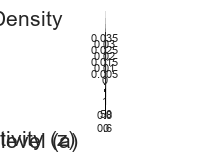

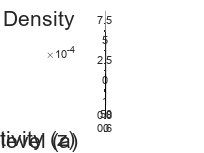

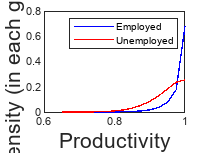

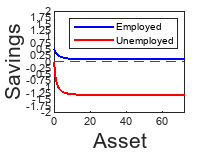

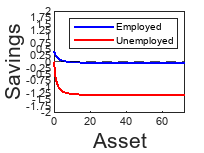

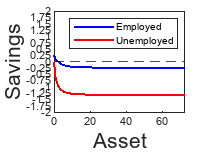

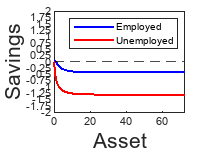

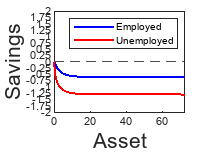

    filenamee = sprintf('Mats - Welfare/Omega_e - %s.mat', taupct);
    save(filenamee,'Omega_e');
    filenameu = sprintf('Mats - Welfare/Omega_u - %s.mat', taupct);
    save(filenameu,'Omega_u');

    filenamece = sprintf('Mats - Consumption/ce - %s.mat', taupct);
    save(filenamece,'ce');
    filenamecu = sprintf('Mats - Consumption/cu - %s.mat', taupct);
    save(filenamecu,'cu');

    filenamexie = sprintf('Mats - Savings/xie - %s.mat', taupct);
    save(filenamexie,'xie');
    filenamexiu = sprintf('Mats - Savings/xiu - %s.mat', taupct);
    save(filenamexiu,'xiu');
    
    filenameJV = sprintf('Mats - Job Value and Wage/JV - %s.mat', taupct);
    save(filenameJV,'JfIJ');
    filenamewg = sprintf('Mats - Job Value and Wage/wg - %s.mat', taupct);
    save(filenamewg,'wg');

    filenameGe = sprintf('Mats - Distributions/Ge - %s.mat', taupct);
    save(filenameGe,'Ge');
    filenameGu = sprintf('Mats - Distributions/Gu - %s.mat', taupct);
    save(filenameGu,'Gu');

    filenamepi = sprintf('Mats - Job Value and Wage/pi - %s.mat', taupct);
    save(filenamepi,'pi');

    filenameWe = sprintf('Mats - Value Function/We - %s.mat', taupct);
    save(filenameWe,'We');
    filenameWu = sprintf('Mats - Value Function/Wu - %s.mat', taupct);
    save(filenameWu,'Wu');
end


writetable(Results, 'Results/Results10.xlsx');
writetable(Omegas,  'Results/Welfare10.xlsx');

toc;

Elapsed time is 1534.928643 seconds.
